clear all
close all
clc

% dynare usmodel_4
% dynare usmodel_longterm
% dynare SWmodel
% dynare SWmodel_longterm_debt
% dynare SW_LTB_RR
dynare SW_SS

Configuring Dynare ...
[mex] Generalized QZ.
[mex] Sylvester equation solution.
[mex] Kronecker products.
[mex] Sparse kronecker products.
[mex] Local state space iteration (second order).
[mex] Bytecode evaluation.
[mex] k-order perturbation solver.
[mex] k-order solution simulation.
[mex] Quasi Monte-Carlo sequence (Sobol).
[mex] Markov Switching SBVAR.

Using 64-bit preprocessor
Starting Dynare (version 4.5.6).
Starting preprocessing of the model file ...
Found 43 equation(s).
Evaluating expressions...done
Computing static model derivatives:
 - order 1
Computing dynamic model derivatives:
 - order 1
 - order 2
Processing outputs ...
done
Preprocessing completed.



STEADY-STATE RESULTS:

labobs  		 0.5509
robs    		 2.73374
pinfobs 		 2
dy      		 0.4
dc      		 0.4
dinve   		 0.4
dw      		 0.4
ewma    		 0
epinfma 		 0
zcapf   		 0
rkf     		 0
kf      		 0
pkf     		 0
cf      		 0
invef   		 0
yf      		 0
labf    		 0
wf      		 0
rrf     		 1.54083e-16
mc      		 -2.42742e-15
zcap    		 2.34342e-15
rk      		 2.82057e-15
k       		 -2.5196e-15
pk      		 0
c       		 8.0685e-15
inve    		 -4.86302e-15
y       		 4.3829e-15
lab     		 4.38566e-15
pinf    		 2
w       		 -4.08468e-15
r       		 -7.91381e-17
a       		 0
b       		 1.88896e-17
g       		 0
qs      		 0
ms      		 2.11041e-17
spinf   		 5.41885e-17
sw      		 1.48852e-17
kpf     		 0
kp      		 -4.86302e-15
rr      		 0.733743
v       		 2.01899e-16
s       		 1.49238e-16

EIGENVALUES:
         Modulus             Real        Imaginary

       2.049e-17       -2.049e-17                0
       2.134e-17       -2.134e-17                0
       5.767e-17        5.767e-17        

MODEL SUMMARY

  Number of variables:         43
  Number of stochastic shocks: 8
  Number of state variables:   21
  Number of jumpers:           13
  Number of static variables:  15


MATRIX OF COVARIANCE OF EXOGENOUS SHOCKS
Variables          ea        eb        eg       eqs        em     epinf        ew     eps_s
ea           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eb           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eg           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eqs          0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
em           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
epinf        0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
ew           0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000  0.000000
eps_s        0.000000  0.000000  0.00

% dynare SW_CS
% dynare SW_SS_LTB
% dynare SW_CS_LTB

color = ['k','b','r'];
c_color = 1;
% Extract variable details from Dynare output

n_ = M_.endo_nbr ;
n_ = n_+1 ; % Constant
l_ = M_.exo_nbr ;

base_model.variable.n_ = n_ ; % Number of endogenous variables
base_model.variable.l_ = l_ ; % Number of exogenous variables
var_names   = cellstr(M_.endo_names) ;
param_names = cellstr(M_.param_names) ;

for ii=1:n_-1
    eval(['base_model.variable.',var_names{ii},'=',int2str(ii),';']) ;
end

for ii=1:M_.param_nbr
    eval(['base_model.param_names.',param_names{ii},'=',int2str(ii),';']) ;
end

base_model.M_  = M_ ;
base_model.oo_ = oo_ ;

base_model.options_ = options_ ;
base_model.solve = 1 ;
base_model.linearize_around_diff_y = 0 ;

out = dyn_to_str(base_model) ;

base_model.mats.Q = out.mats.Q ;
base_model.mats.G = out.mats.G ;

% A0 y_t = A1 y_t-1 + B0 E_t y_t+1 + D0 eps_t 
% y_t = A0^{-1}.A1 y_t-1 + A0^{-1}B0 E_t y_{t+1} ...
base_model.str_mats.A0 = out.mats.A ;
base_model.str_mats.A1 = out.mats.B ;
base_model.str_mats.B0 = out.mats.D ;
base_model.str_mats.D0 = out.mats.E ;
base_model.str_mats.D2 = out.mats.D2 ;
base_model.str_mats.Gamma = out.mats.Gamma ;

% y_ss = Q/(I - Q)
y_ss = (eye(n_-1) - out.mats.Q(1:n_-1,1:n_-1)) \ out.mats.Q(1:n_-1,end)  ;
base_model.y_ss = [y_ss ; 1] ; % Constant

## Simulating a change to the inflation target to 2% (0%)

new_model = base_model;
cpie = 1.005;1;
cr=cpie/(M_.params(new_model.param_names.cbeta)*M_.params(new_model.param_names.cgamma)^(-M_.params(new_model.param_names.csigma)));

M_.params(new_model.param_names.cpie) = cpie;
M_.params(new_model.param_names.cr) = cr;
M_.params(new_model.param_names.conster) = (cr-1)*100;
M_.params(new_model.param_names.constepinf) = (cpie-1)*100;
M_.params(new_model.param_names.crpi) = 2.0443;
M_.params(new_model.param_names.R) = 0.5;

% For dynare 5.3
%[oo_.dr,info,M_,oo_]  = resol(0,M_,options_,oo_) ; 

% For dyanre 4.5.6
% [oo_.dr,info,M_,options_,oo_]  = resol(0,M_,options_,oo_) ;

% dynare usmodel_1

new_model.variable.n_ = n_ ; % Number of endogenous variables
new_model.variable.l_ = l_ ; % Number of exogenous variables
var_names   = cellstr(M_.endo_names) ;
param_names = cellstr(M_.param_names) ;

for ii=1:n_-1
    eval(['new_model.variable.',var_names{ii},'=',int2str(ii),';']) ;
end

for ii=1:M_.param_nbr
    eval(['new_model.param_names.',param_names{ii},'=',int2str(ii),';']) ;
end

new_model.M_  = M_ ;
new_model.oo_ = oo_ ;
new_model.solve = 1 ;
new_model.linearize_around_diff_y = 0;
new_model.options_ = options_;

out1 = dyn_to_str(new_model) ;

new_model.mats.Q = out1.mats.Q ;
new_model.mats.G = out1.mats.G ;

new_model.str_mats.A0 = out1.mats.A ;
new_model.str_mats.A1 = out1.mats.B ;
new_model.str_mats.B0 = out1.mats.D ;
new_model.str_mats.D0 = out1.mats.E ;
new_model.str_mats.D2 = out1.mats.D2 ;
new_model.str_mats.Gamma = out1.mats.Gamma ;

y_new_ss = (eye(n_-1) - out1.mats.Q(1:n_-1,1:n_-1)) \ out1.mats.Q(1:n_-1,end)  ;
new_model.y_ss = [y_new_ss ; 1] ; % Constant

## Simulate an unanticipated disinflation

T = 300; %length of the simulation
Ta = 4; %Date of the announcement
Tstar = 4; %Date of the disinflation policy implementation

y_non = zeros(n_,T);
y_non(:,1) = base_model.y_ss;

if Ta<Tstar

% Allow for announcement date and implementation date to differ
% Do backward induction
Qat = zeros(n_,n_,Tstar-Ta);
Gat = zeros(n_,l_,Tstar-Ta);


% A0 y_t = A1 y_t-1 + B0 E_t y_t+1 + D0 eps_t 

% A = A1/A0
% A = base_model.str_mats.A0\base_model.str_mats.A1;
% A0inv = inv(base_model.str_mats.A0);
% % B = B0/A0
% B = base_model.str_mats.A0\base_model.str_mats.B0;
D0 = base_model.str_mats.D0;
A0 = base_model.str_mats.A0;
A1 = base_model.str_mats.A1;
B0 = base_model.str_mats.B0;
% y_t = A y_t-1 + B E_t y_t+1 + D eps_t

%     Qat(:,:,end) = (eye(n_)-B*new_model.mats.Q)\A;
%     Gat(:,:,end) = (eye(n_)-B*new_model.mats.Q)\A0inv*D0;
    
    Qat(:,:,end) = (A0-B0*new_model.mats.Q)\A1;
    Gat(:,:,end) = (A0-B0*new_model.mats.Q)\D0;

% for t = Tstar-Ta-1:-1:1
%     Qat(:,:,t) = (eye(n_)-B*Qat(:,:,t+1))\A;
%     Gat(:,:,t) = (eye(n_)-B*Qat(:,:,t+1))\A0inv*D0;
% end

for t = Tstar-Ta-1:-1:1
    Qat(:,:,t) = (A0-B0*Qat(:,:,t+1))\A1;
    Gat(:,:,t) = (A0-B0*Qat(:,:,t+1))\D0;
end

Qtilde = zeros(n_,n_,Tstar-Ta);
Gtilde = zeros(n_,l_,Tstar-Ta);

% for t = 1:Tstar-Ta
%     Qtilde(:,:,t) = (eye(n_) - B*Qat(:,:,t))\A;
% end
for t = 1:Tstar-Ta
   Qtilde(:,:,t) = (A0 - B0*Qat(:,:,t))\A1;
end


% Initial policy regime
for t= 2:Ta-1
    y_non(:,t) = base_model.mats.Q*y_non(:,t-1); 
end

% for t = Ta:Tstar-1
%    y_non(:,t) = Qat(:,:,t-Ta+1)*y_non(:,t-1);
% end

for t = Ta:Tstar-1
   y_non(:,t) =  Qtilde(:,:,t-Ta+1)*y_non(:,t-1);
end

for t= Tstar:T
    y_non(:,t) = new_model.mats.Q*y_non(:,t-1); 
end

else
for t= 2:Ta-1
    y_non(:,t) = base_model.mats.Q*y_non(:,t-1); 
end

for t= Tstar:T
    y_non(:,t) = new_model.mats.Q*y_non(:,t-1); 
end
    
end

## Graph outcome

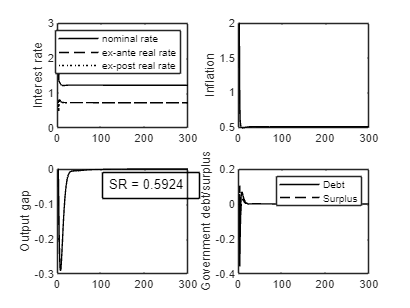

sacrifice_ratio = -sum((y_non(base_model.variable.y,:))/(8-2));
sr_value_rounded = round(sacrifice_ratio, 4);

% Create the annotation with the text "SR = NUMBER"
annotation_text = sprintf('SR = %.4f', sr_value_rounded);
annotation_position = [0.25 0.34 0.25 0.1]; % [x, y, width, height] in normalized coordinates


figure(1)
subplot(2,2,1)
plot(y_non(base_model.variable.robs,:),color(c_color))
ylabel('Interest rate')
hold on
plot(y_non(base_model.variable.rr,:),[color(c_color),'--'])
hold on
plot(y_non(base_model.variable.robs,:)-y_non(base_model.variable.pinfobs,:),[color(c_color),':'])
legend('nominal rate', 'ex-ante real rate', 'ex-post real rate')
subplot(2,2,2)
plot(y_non(base_model.variable.pinfobs,:),color(c_color))
ylabel('Inflation')
hold on
subplot(2,2,3)
% plot(y_non(base_model.variable.dy,:),color(c_color))
plot(y_non(base_model.variable.y,:)-y_non(base_model.variable.yf,:),color(c_color))
% axis([0 T -1 5])
ylabel('Output gap')
hold on
annotation('textbox', annotation_position, 'String', annotation_text, ...
    'FitBoxToText', 'on', 'EdgeColor', 'black', 'BackgroundColor', 'none');
% axis([0 T -0.005 1])
subplot(2,2,4)
plot(y_non(base_model.variable.v,:),color(c_color))
hold on
plot(y_non(base_model.variable.s,:),[color(c_color),'--'])
% axis([0 T -1 4])
ylabel('Government debt/surplus')
legend('Debt', 'Surplus')

hold off

% axis([0 T -0.005 1])
